# PMSM Field-Oriented Controller Optimization

## 1. Theoretical Background and Problem Definition

This script determines the $i_D \;$ and $i_Q$ references of a field oriented controller that minimize the total power losses in the PMSM. By minimizing these power losses, the motor drive system has an optimal energy efficiency.

The PMSM Field-Oriented Controller subsystem has an outer loop of speed control, and an inner loop of current control. The outer loop determines the current references ($i_D \textrm{ref}\;$ and $i_Q \textrm{ref}$) for the inner loop. The choice of current references to provide a desired torque is not unique. It is an underdetermined problem with infinite possible solutions.

To choose the best possible $i_D \textrm{ref}\;$ and $i_Q \textrm{ref}$ for any given operating point, this script solves an optimization problem to determine the table of optimal values for $i_D \textrm{ref}\;$ and $i_Q \textrm{ref}$ that minimize total drive losses for any given operating point (the torque reference $\textrm{Tref}$, rotor mechanical speed $w$, and DC supply voltage $\textrm{Vdc}$).

For a given $\left(\textrm{Tref},\;w,\;\textrm{Vdc}\right)$, find $i_D \textrm{ref}$ and $i_Q \textrm{ref}$ that satisfy:

- 
$$T_{\textrm{motor}} \left(i_D \textrm{ref}\;,\;i_Q \textrm{ref}\right)=\textrm{Tref}$$


- minimize $P_{\textrm{diss}\;} \left(i_D \textrm{ref},i_Q \textrm{ref},w,\textrm{Vdc}\right)$ with fixed $w,\textrm{Vdc}$

### 1.1 Loss Model

There are different sources of power loss in the drive system. The motor produces copper losses and iron losses. The inverter produces switching losses and conduction losses.

The total dissipated power is:


$$P_{\textrm{diss}} =P_{\textrm{copper}} +P_{\textrm{iron}} +P_{\textrm{inverter}}$$


with:

- 
$$P_{\textrm{copper}} =\textrm{Rs}\;\left({i_D }^2 +{i_{Q\;} }^2 \right)$$


- 
$$P_{\textrm{iron}} \left(i_D \;,i_Q \;,w\right)=\textrm{tablelookup}\left({\textrm{IronLossTable},\;i}_D \;,i_Q \;,w\right)$$


- 
$$P_{\textrm{inverter}} \;\left(\textrm{Vdc},I_{\textrm{rms}} \;\right)=\textrm{tablelookup}\left(\textrm{InverterLossTable},\textrm{Vdc},I_{\textrm{rms}} \;\right)\;$$


where:

- $\textrm{Rs}$ is the resistance per stator phase in the motor.

- $w$ is the rotor mechanical speed.

- $i_D \;,i_Q \;$are the D and Q axes currents in the motor.

- $\textrm{Vdc}$ is the DC supply voltage (from the battery).

- $I_{\textrm{rms}} =\sqrt{{i_D }^2 +{i_Q }^2 }\;$ is the RMS current magnitude flowing through the inverter.

#### 1.1.1 Iron Losses

The motor uses the tabulated Steinmetz coefficients model to determine the iron losses:


$$\textrm{IronLossTable}\left(i_D ,i_Q ,w\right)=\left\lbrack k_{\textrm{hr}} \left(i_D ,i_Q \right)+k_{\textrm{hs}} \left(i_D ,i_Q \right)\right\rbrack \frac{\textrm{abs}\left(w\right)\;n_{\textrm{poles}} }{2\pi }+\left\lbrack k_{\textrm{Jr}} \left(i_D ,i_Q \right)+k_{\textrm{Js}} \left(i_D ,i_Q \right)\right\rbrack {\left(\frac{\textrm{abs}\left(w\right)\;n_{\textrm{poles}} }{2\pi }\right)}^2 +\left\lbrack k_{\textrm{er}} \left(i_D ,i_Q \right)+k_{\textrm{es}} \left(i_D ,i_Q \right)\right\rbrack {\left(\frac{\textrm{abs}\left(w\right)n_{\textrm{poles}} }{2\pi }\right)}^{\frac{3}{2}} \;$$


#### 1.1.2 Inverter Losses

The IGBT loss model and some controller parameters such as the PWM switching frequency determine the inverter loss table for copper and switching losses.

See [*getInverterParams.mlx*](http://../utils/getInverterParams.mlx) to learn about the inverter loss models.

### 1.2 Torque Model

The [FEM-Parameterized PMSM (DQ0 flux data)](https://www.mathworks.com/help/physmod/sps/ref/femparameterizedpmsm.html#mw_e80610e3-7437-41a2-8194-6919dbe12eef) directly tabulates the motor torque as a function of D-axis and Q-axis currents, and rotor angle, in the *Torque matrix, T(iD,iQ,theta) *parameter.

In steady-state, the shaft rotates at constant speed. Instantaneously, the torque changes with rotor position, according to the torque table. However, only the average torque per cycle is relevant in this calculations, so it is averaged in the position dimension:

${\bar{T} }_{\textrm{motor}} \left(i_D \;,\;i_Q \right)$ = $\frac{1}{x_2 -x_1 }\int_{x_1 }^{x_2 } \textrm{TorqueMatrix}\left(i_D \;,\;i_Q \;,x\right)\textrm{dx}$ 

## 2. Optimization Setup

For this optimization, the inverter losses are not included in the cost function. Only the motor losses are minimized.

### 2.1 Get model parameters

Load drive model parameters:

model = 'pmsm_foc_drive';
load_system(model);
% MotorDriveTestParams;
SystemParams;

SystemParams.m successful run


Get block parameters relevant to the optimization problem:

% Path to relevant subsystems/blocks
hMotor = [model, '/PMSM/PMSM'];

nPolePairs = PmsmParams.NumPolePairs;
Rs = PmsmParams.StatorResistance;
TorqueMatrix_IBX = PmsmParams.TorqueMat; % Torque matrix, T(I,B,theta)
magVec2 = PmsmParams.CurrMagVec; % Peak current magnitude vector, I
betaVec2 = PmsmParams.CurrAdvAngleVec; % Current advance angle vector, B
xVec2 = PmsmParams.RotorAngleVec; % Rotor electrical angle vector, theta
rotorKhMat_IB = PmsmParams.RotorKhMat; % Rotor hysteresis loss coefficient, k_hr(I,B)
rotorKjMat_IB = PmsmParams.RotorKjMat; % Rotor eddy current loss coefficient, k_Jr(I,B)
statorKhMat_IB = PmsmParams.StatorKhMat; % Stator hysteresis loss coefficient, k_hr(I,B)
statorKjMat_IB = PmsmParams.StatorKjMat; % Stator eddy current loss coefficient, k_Jr(I,B)

Generate optimization parameters from the raw block parameters.

#### 2.1.1 Torque matrix

% 1) Compute TorqueMatrix(I,B) averaging over theta
TorqueMatrix = trapz(xVec2, TorqueMatrix_IBX, 3)/(xVec2(end)-xVec2(1));

% 2) Compute TorqueMatrix(iD,iQ) with transformation from polar to cartesian coordinates (I,B) -> (iD,iQ)
betaVec2 = simscape.Value(betaVec2, get_param(hMotor, 'betaVec2_unit')); % value with unit
betaVec2 = betaVec2.value('rad'); % ensure unit is radians
[Igrid, Bgrid] = ndgrid(magVec2, betaVec2);
% Convention: Option 2. Q leads D, rotor angle measured from A-phase to Q-axis
iDgrid = -Igrid.*sin(Bgrid);
iQgrid = Igrid.*cos(Bgrid);

The geometric convention chosen in the motor corresponds to the following diagram:

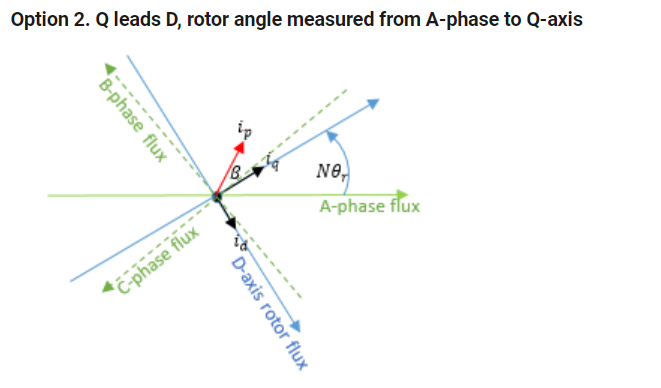

Plot the torque matrix with iD and iQ

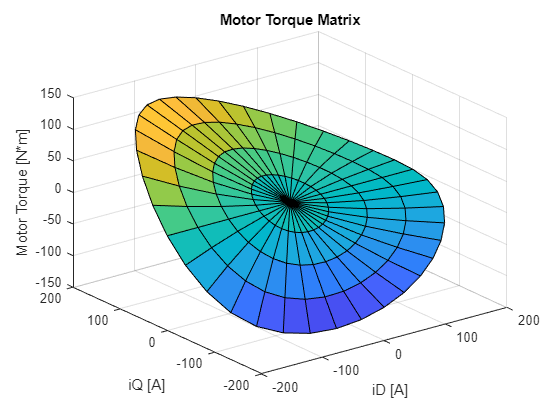

figure();
surf(iDgrid, iQgrid, TorqueMatrix)
title('Motor Torque Matrix')
xlabel('iD [A]');
ylabel('iQ [A]');
zlabel('Motor Torque [N*m]')

% 3) Compute a TorqueMatrix interpolant and function handle
TmotorInterpolant = scatteredInterpolant(iDgrid(:), iQgrid(:), TorqueMatrix(:), 'natural', 'nearest');
TmotorFcn = @(id,iq) TmotorInterpolant(id,iq);

#### 2.1.2 Motor Losses


$$P_{\textrm{motor}} =\textrm{Rs}\;\left({i_D }^2 +{i_{Q\;} }^2 \right)+\textrm{tablelookup}\left({\textrm{IronLossTable},\;i}_D \;,i_Q \;,w\right)$$


with:


$$\textrm{IronLossTable}\left(i_D ,i_Q ,w\right)=\left\lbrack k_{\textrm{hr}} \left(i_D ,i_Q \right)+k_{\textrm{hs}} \left(i_D ,i_Q \right)\right\rbrack \frac{\textrm{abs}\left(w\right)\;n_{\textrm{poles}} }{2\pi }+\left\lbrack k_{\textrm{Jr}} \left(i_D ,i_Q \right)+k_{\textrm{Js}} \left(i_D ,i_Q \right)\right\rbrack {\left(\frac{\textrm{abs}\left(w\right)\;n_{\textrm{poles}} }{2\pi }\right)}^2 +\left\lbrack k_{\textrm{er}} \left(i_D ,i_Q \right)+k_{\textrm{es}} \left(i_D ,i_Q \right)\right\rbrack {\left(\frac{\textrm{abs}\left(w\right)n_{\textrm{poles}} }{2\pi }\right)}^{\frac{3}{2}} \;$$


% 1) Steinmetz interpolants
khInterpolant = scatteredInterpolant(iDgrid(:),iQgrid(:), rotorKhMat_IB(:)+statorKhMat_IB(:),'natural', 'linear');
kJInterpolant = scatteredInterpolant(iDgrid(:),iQgrid(:), rotorKjMat_IB(:)+statorKjMat_IB(:),'natural', 'linear');
% 2) power loss function
PmotorFcn = @(id,iq,w) Rs*(id.^2 + iq.^2) + khInterpolant(id,iq).*(abs(w)*nPolePairs/2/pi) + kJInterpolant(id,iq).*(abs(w)*nPolePairs/2/pi).^2;

Visualize power loss in 2D (for iQ=0)

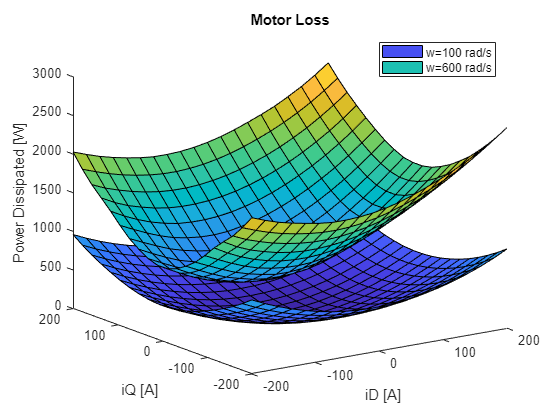

iDvec = linspace(-200,200,20);
iQvec = linspace(-200,200,20);
w1 = 100;
w2 = 500;
[iDg, iQg] = ndgrid(iDvec, iQvec);
PmotorValsw1 = PmotorFcn(iDg,iQg,w1*ones(size(iDg)));
PmotorValsw2 = PmotorFcn(iDg,iQg,w2*ones(size(iDg)));
figure();
hold on;
surf(iDg, iQg, PmotorValsw1);
surf(iDg, iQg, PmotorValsw2);
hold off;
title('Motor Loss')
xlabel('iD [A]');
ylabel('iQ [A]');
zlabel('Power Dissipated [W]')
legend('w=100 rad/s', 'w=600 rad/s')

view([-35 19])

## 3. Run Optimization Algorithm

trqVec = linspace(-50,100,20);
rpmVec = linspace(-7000,7000,20);
% Placeholder for solution
iDrefOptimal = nan([length(trqVec), length(rpmVec)]);
iQrefOptimal = nan([length(trqVec), length(rpmVec)]);
exitFlagMat = nan([length(trqVec), length(rpmVec)]);
% Solve an optimization for each trq,rpm values
id = optimvar('id', 'LowerBound',-300,'UpperBound',300);
iq = optimvar('iq', 'LowerBound',-300,'UpperBound',300);
x0 = struct();
x0.id = 0;
x0.iq = 0;
lenTrqVec = length(trqVec);
lenRpmVec = length(rpmVec);
tic;
for idxTrq = 1:lenTrqVec 
    for idxRpm = 1:lenRpmVec
        w = 2*pi/60*rpmVec(idxRpm);
        trq = trqVec(idxTrq);

        fobj = @(x,y) PmotorFcn(x,y,w); % Minimize Pmotor
        prob = optimproblem('Objective',fcn2optimexpr(fobj,id,iq));
        optimoptions(prob, "Algorithm","interior-point",...
                           "EnableFeasibilityMode",true,...
                           "SubproblemAlgorithm","cg");

        TorqueConstraint = fcn2optimexpr(TmotorFcn,id,iq) == trq;
        % Apply torque constraint
        prob.Constraints.constr = TorqueConstraint;

        if idxTrq==1 && idxRpm==1 % first optimization
            % Initial guess id=0,iq=0 
            x0.id = 0;
            x0.iq = 0;
        elseif idxTrq > 1 % Initial guess: optimal previously solved
            x0.id = iDrefOptimal(idxTrq-1, idxRpm);
            x0.iq = iQrefOptimal(idxTrq-1, idxRpm);
        else % idxTrq==1 && idxRpm>1
            x0.id = iDrefOptimal(idxTrq, idxRpm-1);
            x0.iq = iQrefOptimal(idxTrq, idxRpm-1);
        end

        [sol,fval,exitflag,output] = solve(prob, x0);
        exitFlagMat(idxTrq, idxRpm) = exitflag;
        iDrefOptimal(idxTrq, idxRpm)=sol.id;
        iQrefOptimal(idxTrq, idxRpm)=sol.iq;
    end
end

Solving problem using fmincon.

Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc

Elapsed time is 30.899775 seconds.


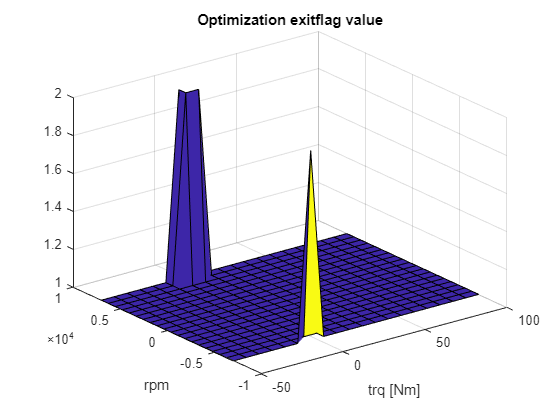

% Check convergence: if flag<0, not converged
figure();
surf(trqVec,rpmVec,exitFlagMat')
title('Optimization exitflag value')
xlabel('trq [Nm]')
ylabel('rpm')

if all(exitFlagMat(:) > 0)
    disp('SUCCESS: Optimization CONVERGED for all operating points')
else
    disp('FAILURE: Optimization NOT CONVERGED for all operating points')
end

SUCCESS: Optimization CONVERGED for all operating points


To correctly interpret exitflag values, visit [this](https://www.mathworks.com/help/optim/ug/optim.problemdef.optimizationproblem.solve.html#mw_433feacd-de58-4e3b-b124-a7a0f588f4fc_sep_shared-exitflag) documentation page:

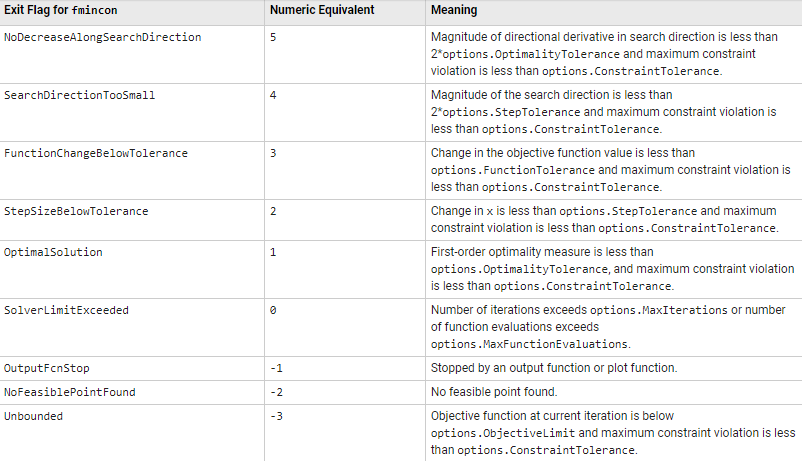

## 4. Plot Results

### 4.1 Plot the solution

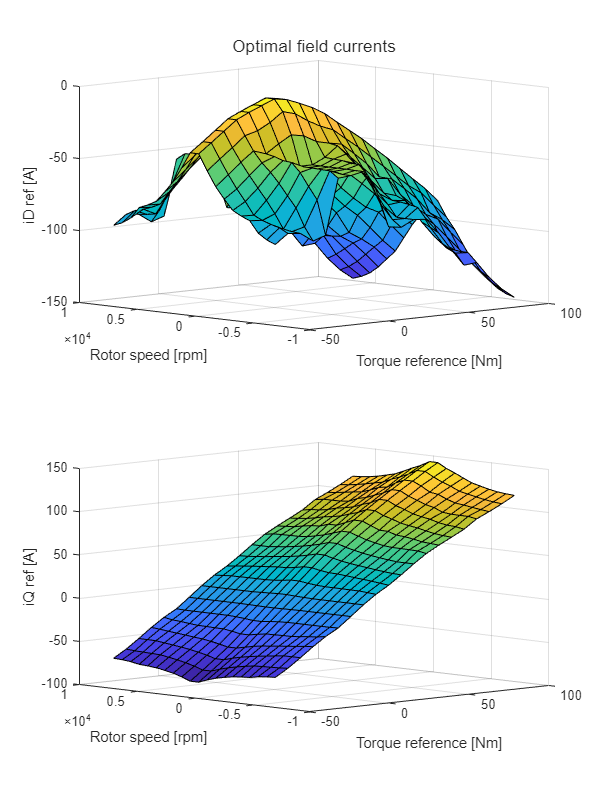

hFig3 = figure();
hFig3.Position = [10 10 720 960];
hTile = tiledlayout(hFig3,2,1);
nexttile; % tile 1
title(hTile,'Optimal field currents')
surf(trqVec,rpmVec, iDrefOptimal');
xlabel('Torque reference [Nm]');
ylabel('Rotor speed [rpm]');
zlabel('iD ref [A]')
nexttile;
surf(trqVec,rpmVec, iQrefOptimal');
xlabel('Torque reference [Nm]');
ylabel('Rotor speed [rpm]');
zlabel('iQ ref [A]')
hAxs = hTile.Children;
hAxs(1).View = [-44,10];
hAxs(2).View = [-44,10];

### 4.2 Validate the solution

Let's plot the power loss and torque constraint for a particular operating point, to check if the solver actually converged to the global minima.

idxTest = [12,12];
trqtest = trqVec(idxTest(1));
wtest = 2*pi/60*rpmVec(idxTest(2));

[idg,iqg]=ndgrid(linspace(-200,200,20),linspace(-200,200,20));
idxMatchTrqConstraint = abs(TmotorFcn(idg,iqg)-trqtest)<5;
idtrq = idg(idxMatchTrqConstraint);
iqtrq = iqg(idxMatchTrqConstraint);
lossTrq = PmotorFcn(idtrq,iqtrq, wtest);
idxOpt = find(lossTrq==min(lossTrq));
disp(['iDref found : ', num2str(iDrefOptimal(idxTest(1), idxTest(2))), ' A. Optimal within 5 N*m of torque constraint tolerance:' num2str(idtrq(idxOpt(1))), ' A']);

iDref found : -36.2513 A. Optimal within 5 N*m of torque constraint tolerance:-31.5789 A


disp(['iQref found : ', num2str(iQrefOptimal(idxTest(1), idxTest(2))), ' A. Optimal within 5 N*m of torque constraint tolerance:' num2str(iqtrq(idxOpt(1))), ' A']);

iQref found : 58.8204 A. Optimal within 5 N*m of torque constraint tolerance:52.6316 A


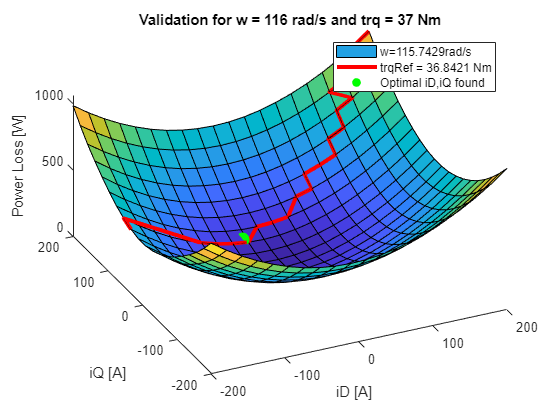

figure();
PmotorThisW = PmotorFcn(idg,iqg,wtest*ones(size(idg)));
hold on;
surf(idg,iqg,PmotorThisW);
plot3(idtrq,iqtrq,lossTrq, 'LineWidth', 3, 'Color', [1 0 0]);
iDrefOpt = iDrefOptimal(idxTest(1), idxTest(2));
iQrefOpt = iQrefOptimal(idxTest(1), idxTest(2));
scatter3(iDrefOpt, iQrefOpt, PmotorFcn(iDrefOpt, iQrefOpt, wtest), 'go', 'MarkerFaceColor', 'g', 'SizeData', 100);
hold off;
xlabel('iD [A]')
ylabel('iQ [A]')
zlabel('Power Loss [W]');
legend(['w=', num2str(wtest), 'rad/s'], ['trqRef = ', num2str(trqtest), ' Nm'], 'Optimal iD,iQ found')
title(['Validation for w = ', num2str(round(wtest)), ' rad/s and trq = ', num2str(round(trqtest)), ' Nm'])
view([-25 47])

## 5. Save Results

Save optimal control parameters into ControllerParams

ControllerParams.OuterLoop.RpmVec = rpmVec;
ControllerParams.OuterLoop.TrqRefVec = trqVec;
ControllerParams.OuterLoop.VdcVec = [300, 500];
ControllerParams.OuterLoop.iDrefMat = repmat(iDrefOptimal',1,1,2); % trq,spd -> spd,trq,voltage format
ControllerParams.OuterLoop.iQrefMat = repmat(iQrefOptimal',1,1,2); % trq,spd -> spd,trq,voltage format
% Create a variable "OptimalControllerParams" to use without need to rerun
% the optimization:
OptimalControllerParams = ControllerParams;

Copyright 2022 The MathWorks, Inc